# Fine-Tune BERT to Classify Text Data in MATLAB®

This example shows how to fine-tune a pretrained BERT model for performing text classification. First, add new layers for classification. Then, retrain the model to fine-tune it, using the original parameters as a starting point. It includes three steps.

1.	Preprocess text data and initialize BERT model

2.	Set up and train the network

3.	Test the model

This example shows the steps for fine-tuning BERT in detail. An alternative approach for document classification using BERT is to use [trainBERTDocumentClassifier](https://www.mathworks.com/help/textanalytics/ref/trainbertdocumentclassifier.html) function.

## Preprocess Text Data and Initialize BERT Model

### Load Data

In this example, you are classifying factory reports. The file `factoryReports.csv` contains these reports, including a text description and categorical labels for each report. 

The example requires data to run. To download the data: : 

- Go to [https://www.mathworks.com/help/textanalytics/ug/create-simple-text-model-for-classification.html](https://www.mathworks.com/help/textanalytics/ug/create-simple-text-model-for-classification.html). 

- Click on the button "Copy Command" on the top right of the page and paste it in MATLAB Command Window. This will open the example in the directory where the CSV file is stored. 

- Copy the CSV file from the example, and paste it in the cloned repository.

- If the file is saved in a different location, change the code to point to the file.

filename = "factoryReports.csv"; % point to the location where it is saved
data = readtable(filename,TextType="string");
head(data)

                                 Description                                       Category          Urgency          Resolution         Cost 
    _____________________________________________________________________    ____________________    ________    ____________________    _____

    "Items are occasionally getting stuck in the scanner spools."            "Mechanical Failure"    "Medium"    "Readjust Machine"         45
    "Loud rattling and banging sounds are coming from assembler pistons."    "Mechanical Failure"    "Medium"    "Readjust Machine"         35
    "There are cuts to the power when starting the plant."                   "Electronic Failure"    "High"      "Full Replacement"      16200
    "Fried capacitors in the assembler."                                     "Electronic Failure"    "High"      "

classes = categories(categorical(data.Category));
data.Category = categorical(data.Category);

### Initialize BERT Model

Initialize a pre-trained BERT-tiny model and tokenizer for processing text. If the Text Analytics Toolbox™ Model for *BERT-Tiny* *Network *support package is not installed, then the function provides a link to the required support package in the Add-On Explorer. To install the support package, click the link, and then click **Install**. For more information on pretrained BERT models in MATLAB, see: [Pretrained BERT model - MATLAB bert (mathworks.com)](https://www.mathworks.com/help/textanalytics/ref/bert.html).

[net, tokenizer] = bert("Model", "tiny");

### Split Data Into Training, Validation, and Test

Split the data into training, validation, and test sets. Use 80% of the data for training, 10% for validation, and 10% for testing.

rng("default");

cvp = cvpartition(data.Category,'Holdout',0.2);
dataTrain = data(training(cvp),:);
dataRest = data(test(cvp),:);

cvp = cvpartition(dataRest.Category,'Holdout',0.5);
dataVal = dataRest(training(cvp),:);
dataTest = dataRest(test(cvp),:);

### Preprocess Data

Tokenize and preprocess the training data using the helper function `prepareData.`

dataTrain = prepareData(dataTrain, tokenizer);
dataVal = prepareData(dataVal, tokenizer);
dataTest = prepareData(dataTest, tokenizer);

## Set Up and Train Network

Modify the BERT model by adding three layers:

- a 1-D indexing layer that extracts the data from the first index of the time dimension of the input data

- a fully connected layer with number of outputs being same as the number of classes

- a softmax layer that takes the raw output scores from the previous layer of the network and transforms them into probabilities by applying the softmax function

outputLayer = net.OutputNames{1};
newLayers = [indexing1dLayer; fullyConnectedLayer(length(classes)); softmaxLayer];
net = addLayers(net, newLayers);
net = connectLayers(net, outputLayer, "layer");

Initialize the network. View the network architecture using the `analyzeNetwork` function.

net = initialize(net);
analyzeNetwork(net)

Create mini-batch queue objects for the training and validation data to feed into the model during training.

trainMbq = createBERTMbq(dataTrain, tokenizer.PaddingCode);
valMbq = createBERTMbq(dataVal, tokenizer.PaddingCode);

### Define Training Parameters

Set the training parameters such as the mini-batch size, number of epochs, and learning rate.

miniBatchSize = 16;
numEpochs = 30;
learnRate = 1e-5;

options = trainingOptions("adam", ...
    MaxEpochs=numEpochs, ...
    InitialLearnRate=learnRate, ...
    MiniBatchSize=miniBatchSize, ...
    ValidationData=valMbq,...
    Shuffle="every-epoch", ...
    Metrics="accuracy",...
    Verbose=false,...
    Plots="training-progress");

### Train Model

Train the BERT model using [`trainnet`](https://www.mathworks.com/help/deeplearning/ref/trainnet.html?s_tid=doc_ta) with the specified loss function and training options.

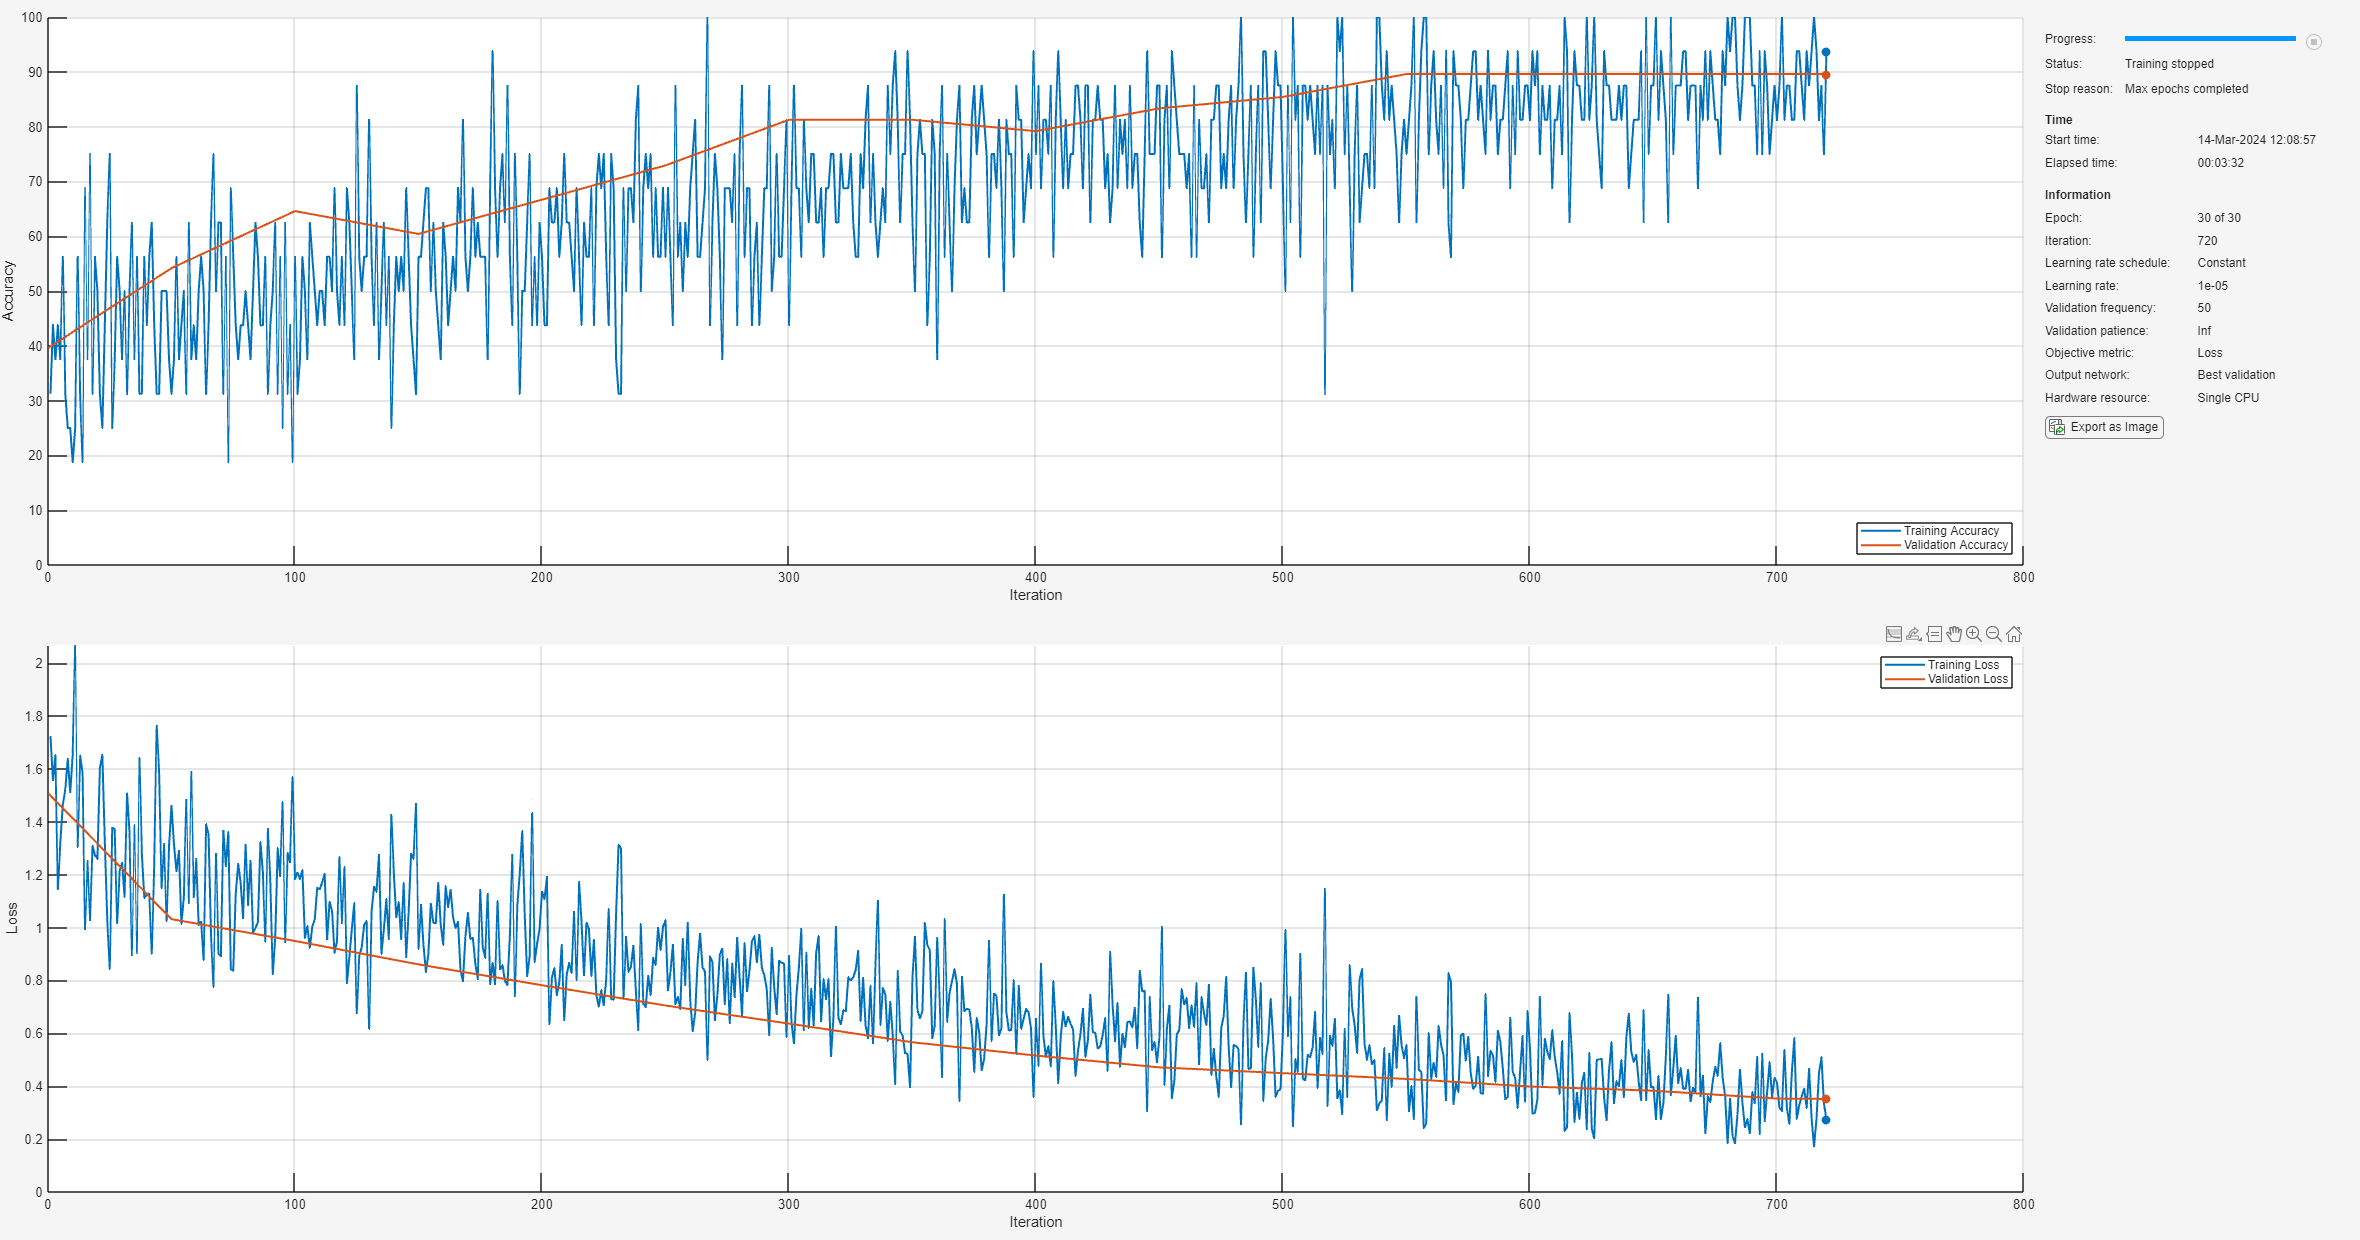

net = trainnet(trainMbq, net, "crossentropy", options);

## Test Model

Evaluate the model on the test data and calculate the accuracy metric.

testInputIds = arrayDatastore({dataTest.inputIds}',OutputType="same");
testSegIds = arrayDatastore({dataTest.segIds}',OutputType="same");
cds = combine(testInputIds, testSegIds);

testMbq = minibatchqueue(cds, 3, ... % 3 outputs: inputIds, mask, segmentIds
    MiniBatchFcn=@(inputIds,segmentIds) preprocessPredictors(inputIds, ...
    segmentIds, ...
    tokenizer.PaddingCode), ...
    MiniBatchFormat=["CTB" "CTB" "CTB"]);


YP = minibatchpredict(net, testMbq, MiniBatchSize=miniBatchSize);
YPred = scores2label(YP, classes);
YTest = [dataTest.class];
accuracy = sum(YPred == YTest)/numel(YTest)

accuracy = 0.8750

## Supporting Functions

This function prepares text data using BERT tokenizer.

function allData = prepareData(data, tokenizer)
maxSeqLength = 128;
numElements = height(data);
allData(numElements) = struct("inputIds", [], ...
    "segIds", [], ...
    "class", []);

% Process each data element
for i = 1:numElements
    description = data(i, :).Description;

    % Tokenize and truncate input
    [inputIds, segIds] = encode(tokenizer, description);
    inputIds = inputIds{:};
    segIds = segIds{:};

    % If inputIds is larger than the maximum allowed length, then it gets truncated
    if numel(inputIds) > maxSeqLength
        inputIds = [inputIds(1:maxSeqLength-1), tokenizer.SeparatorCode];
        segIds = segIds(1:maxSeqLength);
    end
    allData(i).inputIds = inputIds;
    allData(i).segIds = segIds;  
    allData(i).class = data(i, :).Category;

end

end

This function creates mini-batche queues for fine-tuning the BERT using `arrayDatastore`.

function mbq = createBERTMbq(data, paddingValue)
inputIds = {data.inputIds}';
segIds = {data.segIds}';
class = {data.class}';

XTrainDs = arrayDatastore(inputIds, OutputType="same");
STrainDs = arrayDatastore(segIds, OutputType="same");
YTrainDs = arrayDatastore(class);
cds = combine(XTrainDs, STrainDs, YTrainDs);

mbq = minibatchqueue(cds,4,... % 4 outputs: inputIds, mask, segmentIds, targets
    MiniBatchFcn=@(inputIds,segmentIds, targets) preprocessMiniBatch(inputIds, ...
    segmentIds, ...
    targets, ...
    paddingValue), ...
    MiniBatchFormat=["CTB" "CTB" "CTB" "CB"]);
end


This function extracts input IDs, masks, and segment IDs from the input data and one-hot encodes class data.

function [inputIds, mask, segmentIds, targets] = preprocessMiniBatch(inputIds, ...
    segmentIds, targets, paddingValue)
[inputIds, mask, segmentIds] = preprocessPredictors(inputIds, segmentIds, paddingValue);
targets = [targets{:}];
targets = onehotencode([targets{:}], 1);
end

This function pads the input IDs and segment IDs of the predictors to make those uniform in length.  

function [inputIds, mask, segmentIds] = preprocessPredictors(inputIds, segmentIds, paddingValue)
[inputIds, mask] = padsequences(inputIds, 2,"PaddingValue",paddingValue);
segmentIds = padsequences(segmentIds, 2,"PaddingValue",paddingValue);
end

*Copyright 2024 The MathWorks, Inc.*